clc
clear




%Set up directory and paths
filePath = matlab.desktop.editor.getActiveFilename;
folderPath = erase(filePath,'data_analysis_1_0_0_iso.mlx');
cd(folderPath)
cd ..
addpath("data/")
addpath("input/")
addpath("src/")

cd ./data

%Read database file
material_database_mat_file = load("input/microstructures_object_array_final_isostrain.mat");
material_database = material_database_mat_file.microstructure_array;



## Transform data to table

%% Create table


% for i=1:1:length(microstructure_array)
%     
%     current_microstructure = microstructure_array(i);
% 
%     Key(i) = i;
%     f_alpha(i) = current_microstructure.f_alpha
%     f_mart(i) = current_microstructure.f_mart
%     f_beta(i) = current_microstructure.f_beta
%     l_thickness(i) = current_microstructure.lath_thickness
% 
%     Yield_zz(i) = 
% 
% 
% end



%Loop over all microstructures

i_alpha_0=1;
i_beta_0=1;
i_mart_0=1;

for n = 1:1:length(material_database)
    
    microstructure = material_database(n);
    
    if microstructure.f_alpha == 0.0
        yield_ZZ_for_f_alpha_0(i_alpha_0) = microstructure.Yield_stresses(1);
        f_beta_for_f_alpha_0(i_alpha_0) = microstructure.f_beta;
        f_mart_for_f_alpha_0(i_alpha_0) = microstructure.f_mart;
        i_alpha_0=i_alpha_0+1;
    end

    if microstructure.f_beta == 0.
        yield_ZZ_for_f_beta_0(i_beta_0) = microstructure.Yield_stresses(1);
        f_mart_for_f_beta_0(i_beta_0) = microstructure.f_mart;
        f_alpha_for_f_beta_0(i_beta_0) = microstructure.f_alpha;
        i_beta_0=i_beta_0+1;
    end

    if microstructure.f_mart == 0.
        yield_ZZ_for_f_mart_0(i_mart_0) = microstructure.Yield_stresses(1);
        f_beta_for_f_mart_0(i_mart_0) = microstructure.f_beta;
        f_alpha_for_f_mart_0(i_mart_0) = microstructure.f_alpha;
        i_mart_0=i_mart_0+1;
    end

end

## Figures

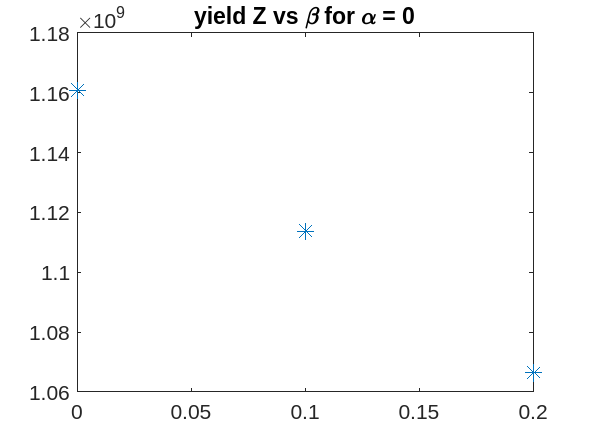



figure()
plot(f_beta_for_f_alpha_0,yield_ZZ_for_f_alpha_0,"*")
title('yield Z vs \beta for \alpha = 0')

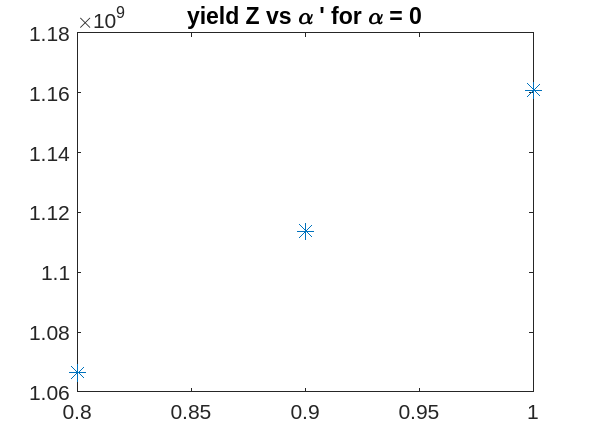


figure()
plot(f_mart_for_f_alpha_0,yield_ZZ_for_f_alpha_0,"*")
title("yield Z vs \alpha ' for \alpha = 0")

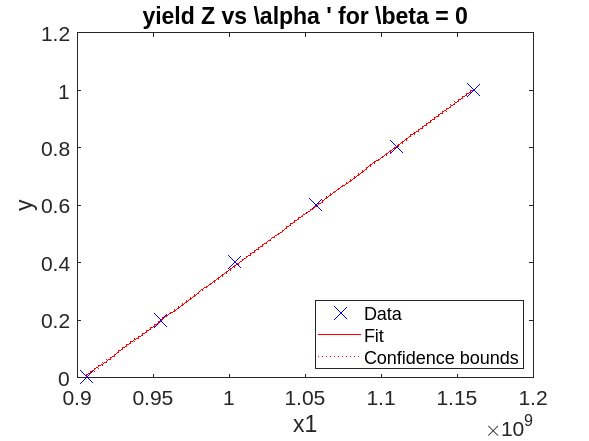


figure()
mdl = fitlm(yield_ZZ_for_f_beta_0, f_mart_for_f_beta_0);
plot(mdl);
title("yield Z vs \alpha ' for \beta = 0")

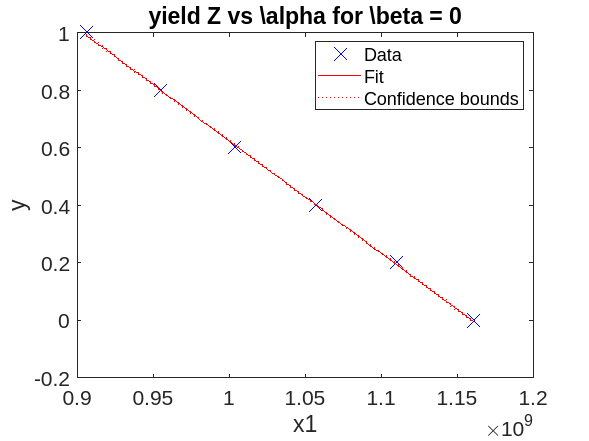


figure()
mdl = fitlm(yield_ZZ_for_f_beta_0, f_alpha_for_f_beta_0);
plot(mdl);
title("yield Z vs \alpha for \beta = 0")